clear; clc;

%% 1
rng(13)

p = 0.35 + (0.95 - 0.35) * rand(1,40);

result = rand(5000,40) < p;

score = sum(result,2);

avg_score = mean(score);
std_score = std(score);

fprintf('평균 점수 = %.4f\n', avg_score);

평균 점수 = 25.8372


fprintf('표준편차 = %.4f\n', std_score);

표준편차 = 2.8083


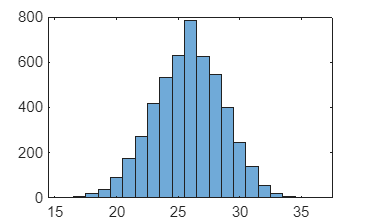


figure;
histogram(score);


ratio = mean(score >= avg_score);

fprintf('평균 이상 학생 비율 = %.4f\n', ratio);

평균 이상 학생 비율 = 0.5640



%% 2
clear; clc;

weight = 100 + 4 * randn(10000,20);

avg_weight = mean(weight,2);

fail = (avg_weight < 98) | (avg_weight > 102);

fail_ratio = mean(fail);

fprintf('불합격률 = %.6f\n', fail_ratio);

불합격률 = 0.023600


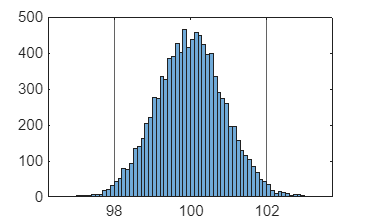


figure;
histogram(avg_weight);
xline(98);
xline(102);


%% 3
clear; clc;

N = randn(100000,1);

S = 1.8 + N;

success = S >= 1.2;

success_rate = mean(success);

fprintf('감지 성공률 = %.6f\n', success_rate);

감지 성공률 = 0.725100


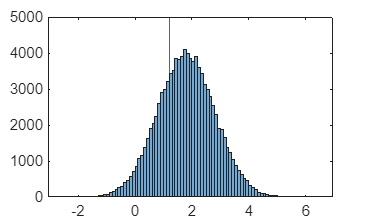


figure;
histogram(S);
xline(1.2);

%% 4
clear; clc;

order_num = poissrnd(180,365,1);

poissrnd에는 Statistics and Machine Learning Toolbox이(가) 필요합니다.


total_time = zeros(365,1);

for i = 1:365

    process_time = 6 + 2 * randn(order_num(i),1);

    process_time(process_time < 0) = 0;

    total_time(i) = sum(process_time);

end

ratio = mean(total_time > 1200);

fprintf('1200분 초과 비율 = %.4f\n', ratio);

figure;
plot(order_num);

figure;
plot(total_time);

figure;
scatter(order_num, total_time);


%% 5
clear; clc;

measure = 25 + 0.8 * randn(10000,30);

avg_measure = mean(measure,2);

event = (avg_measure >= 24.7) & (avg_measure <= 25.3);

prob = mean(event);

fprintf('확률 = %.6f\n', prob);

single_sensor = measure(:,1);

figure;
histogram(single_sensor);
hold on;
histogram(avg_measure);
legend('센서 1개','센서 30개 평균');


%% 6
clear; clc;

r = 0.0008 + 0.015 * randn(5000,60);

asset = zeros(5000,60);

asset(:,1) = 100 * (1 + r(:,1));

for i = 2:60
    asset(:,i) = asset(:,i-1) .* (1 + r(:,i));
end

final_asset = asset(:,60);

fprintf('평균 = %.4f\n', mean(final_asset));
fprintf('최솟값 = %.4f\n', min(final_asset));
fprintf('최댓값 = %.4f\n', max(final_asset));

prob = mean(final_asset < 100);

fprintf('100보다 작을 확률 = %.4f\n', prob);

figure;
plot(asset(1:30,:)');


%% 7
clear; clc;

arrival_interval = exprnd(8,300,1);

arrival_time = cumsum(arrival_interval);

service_time = 10 + 3 * randn(300,1);

service_time(service_time < 0) = 1;

start_time = zeros(300,1);
finish_time = zeros(300,1);

start_time(1) = arrival_time(1);
finish_time(1) = start_time(1) + service_time(1);

for i = 2:300

    start_time(i) = max(arrival_time(i), finish_time(i-1));

    finish_time(i) = start_time(i) + service_time(i);

end

wait_time = start_time - arrival_time;

fprintf('평균 대기시간 = %.4f\n', mean(wait_time));
fprintf('최대 대기시간 = %.4f\n', max(wait_time));

ratio = mean(wait_time > 20);

fprintf('20분 초과 비율 = %.4f\n', ratio);

figure;
histogram(wait_time);


%% 8
clear; clc;

p = [0.72 0.81 0.67 0.90 0.76];

R = rand(100000,5);

detect = R < p;

detect_num = sum(detect,2);

success = detect_num >= 3;

prob = mean(success);

fprintf('시스템 감지 확률 = %.6f\n', prob);

figure;
histogram(detect_num,0:6);


%% 9
clear; clc;

stage1 = rand(50000,1) < 0.94;

stage2 = false(50000,1);

idx1 = find(stage1);

stage2(idx1) = rand(length(idx1),1) < 0.91;

stage3 = false(50000,1);

idx2 = find(stage2);

stage3(idx2) = rand(length(idx2),1) < 0.88;

final_pass = mean(stage3);

fprintf('최종 합격률 = %.6f\n', final_pass);

fail1 = sum(~stage1);

fail2 = sum(stage1 & ~stage2);

fail3 = sum(stage2 & ~stage3);

pass_num = sum(stage3);

result = [fail1 fail2 fail3 pass_num];

figure;
bar(result);


%% 10
clear; clc;

server_noise = 35 * randn(10000,1);

overload = rand(10000,1) < 0.12;

power_usage = 500 + server_noise + 120 * overload;

ratio = mean(power_usage > 650);

fprintf('650 초과 비율 = %.6f\n', ratio);

figure;
histogram(power_usage);

avg_overload = mean(power_usage(overload));

avg_normal = mean(power_usage(~overload));

fprintf('과부하 발생일 평균 = %.4f\n', avg_overload);
fprintf('과부하 비발생일 평균 = %.4f\n', avg_normal);